## Homework 5.4

clear all;
close all;
clc;

format long;

Consider the linear system $Ax = b$ with

A = [1 10^10 1 1;
    10^10 1 1 10^10
    1 1 10^-10 1
    1 10^10 1 10^10]

A = 	1.0e+10 *

   0.000000000100000   1.000000000000000   0.000000000100000   0.000000000100000
   1.000000000000000   0.000000000100000   0.000000000100000   1.000000000000000
   0.000000000100000   0.000000000100000   0.000000000000000   0.000000000100000
   0.000000000100000   1.000000000000000   0.000000000100000   1.000000000000000



b = [10^(10)+3 2*10^(10)+2 3+10^-10 2*10^(10)+2]'

b = 	1.0e+10 *

   1.000000000300000
   2.000000000200000
   0.000000000300000
   2.000000000200000


### a. Solve the system using LU decomposition with pivoting

[L, U, P] = lu(A)

L =    1.000000000000000                   0                   0                   0
   0.000000000100000   1.000000000000000                   0                   0
   0.000000000100000   0.000000000100000   1.000000000000000                   0
   0.000000000100000   1.000000000000000                   0   1.000000000000000


U = 	1.0e+10 *

   1.000000000000000   0.000000000100000   0.000000000100000   1.000000000000000
                   0   1.000000000000000   0.000000000100000  -0.000000000000000
                   0                   0  -0.000000000000000  -0.000000000000000
                   0                   0                   0   0.999999999900000


P =      0     1     0     0
     1     0     0     0
     0     0     1     0
     0     0     0     1


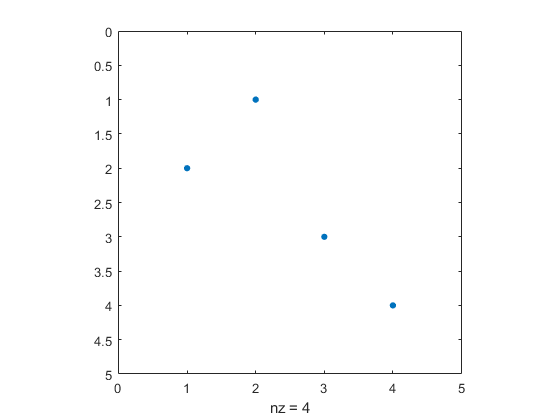


spy(P)


Pb = P*b;

y = L \ Pb

y = 	1.0e+10 *

   2.000000000200000
   1.000000000100000
  -0.000000000000000
   0.999999999900000


x = U \ y

x =    1.000000000000000
   1.000000000000000
   1.000000578563020
   1.000000000000000


### b. Compute the infinity norm of the error associated with the solution of the previous item

n = length(A);
infnorm_A = max(sum(A(1:n,:)))

infnorm_A =      2.000000000200000e+10


### c. Can we apply the Cholesky decomposition to matrix $A$?

In order to check it we have to verify that $A$ is *spd*

if A == A'
    fprintf('A is symmetric')
else
    fprintf('A is not symmetric')
end

A is symmetric


eig_A = eig(A)

eig_A = 	1.0e+10 *

  -1.246979603589456
  -0.000000000000000
   0.445041867890588
   1.801937735898869


if eig(A) > 0
    fprintf('A is positive definite')
else
    fprintf('A is not positive definite')
end

A is not positive definite

A is not positive definite, so we cannot apply the Cholesky decomposition

### d. Is the normalized residual $||b-Ax|| / ||b||$ a good estimator for the relative error?